# M E 325 Exam #1

### Problem 1

A 0.004 inch crack is found in a machine component fabricated from a material with the following properties:


$$S_{\mathrm{ut}} =185\mathrm{kpsi}$$



$$S_y =170\mathrm{kpsi}$$



$$K_{\mathrm{IC}} =73\mathrm{kspi}\sqrt{\mathrm{in}}$$



$$C=3\ldotp 8\times {10}^{-11} \frac{\mathrm{in}}{\mathrm{cycle}}\mathrm{kpsi}\sqrt{\mathrm{in}}$$



$$m=3$$


Sut = 185; % kpsi
Sy = 170; % kpsi
Kic = 73; % 73 kpsi * in^(1/2)
C = 3.8e-11; % in/cycle * kpsi * in^(1/2)
m = 3; 

The part has a cross-section that is 1/4 inch wide and 1/2 inch thick and its length is 2.00 inches. A normal force varies from a value of 500lb to 0lb and a bending moment is applied that varies between a maximum value of 1200 in-lb and a minimum of 0 in-lb. Both loads result in tensile stresses that cause mode I loading. The geometry correction factors for both the axial force and the bending moment can be assumed to be $\beta =1\ldotp 07$.

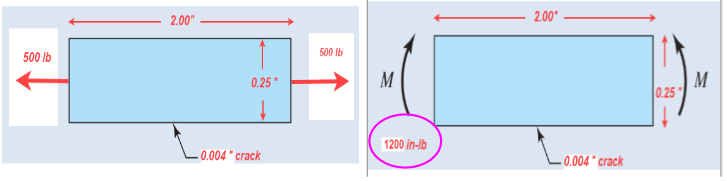

#### Determine:

- $a_f$, the critical crack length

- $N$, the number of cycles, $N$, until the critical crack length is reached.

- $n_{\mathrm{yield}}$, the factoir of safety against yielding

- $\sigma_c$, the critical stress based on LEFM analysis.

M = 1200; % lb-in
F = 500; % lb

h = 0.5; % in
b = 0.25; % in

I = b*h^3/12; % in^4
stress_bending = M*(h/2)/I; % psi

A = b*h; % in^2
stress_tension = F/A; % psi